## Use MBSFN to serve all UE efficiently.

**Load data and plot initialize constant.**

proj_folder = "MBSFN area multiple coverage";
parent_f = fullfile(proj_folder, "MBSFN_Area_7site");
center = load(fullfile(parent_f, "MBSFN_Area_7site_center_outlier_clear.mat"));
left = load(fullfile(parent_f,"MBSFN_Area_7site_left_outlier_clear.mat"));
upleft = load(fullfile(parent_f,"MBSFN_Area_7site_upleft_outlier_clear.mat"));
center_c_list = sort(unique(center.UE_attached_eNodeB));
left_c_list = sort(unique(left.UE_attached_eNodeB));
upleft_c_list = sort(unique(upleft.UE_attached_eNodeB));
x_lim = [-2100, 2100];
y_lim = [-2100, 2100];
mk_size = 9;

**Three MBSFN areas: center, left, upleft.**

**Each area consists of 21 cells.**

f_h = figure("Position", [0, 0, 801, 693]);
orange = [0.8500, 0.3250, 0.0980];
green = [0.4660, 0.6740, 0.1880];
purple = [0.4940, 0.1840, 0.5560];
area = "Left"

area = "Left"

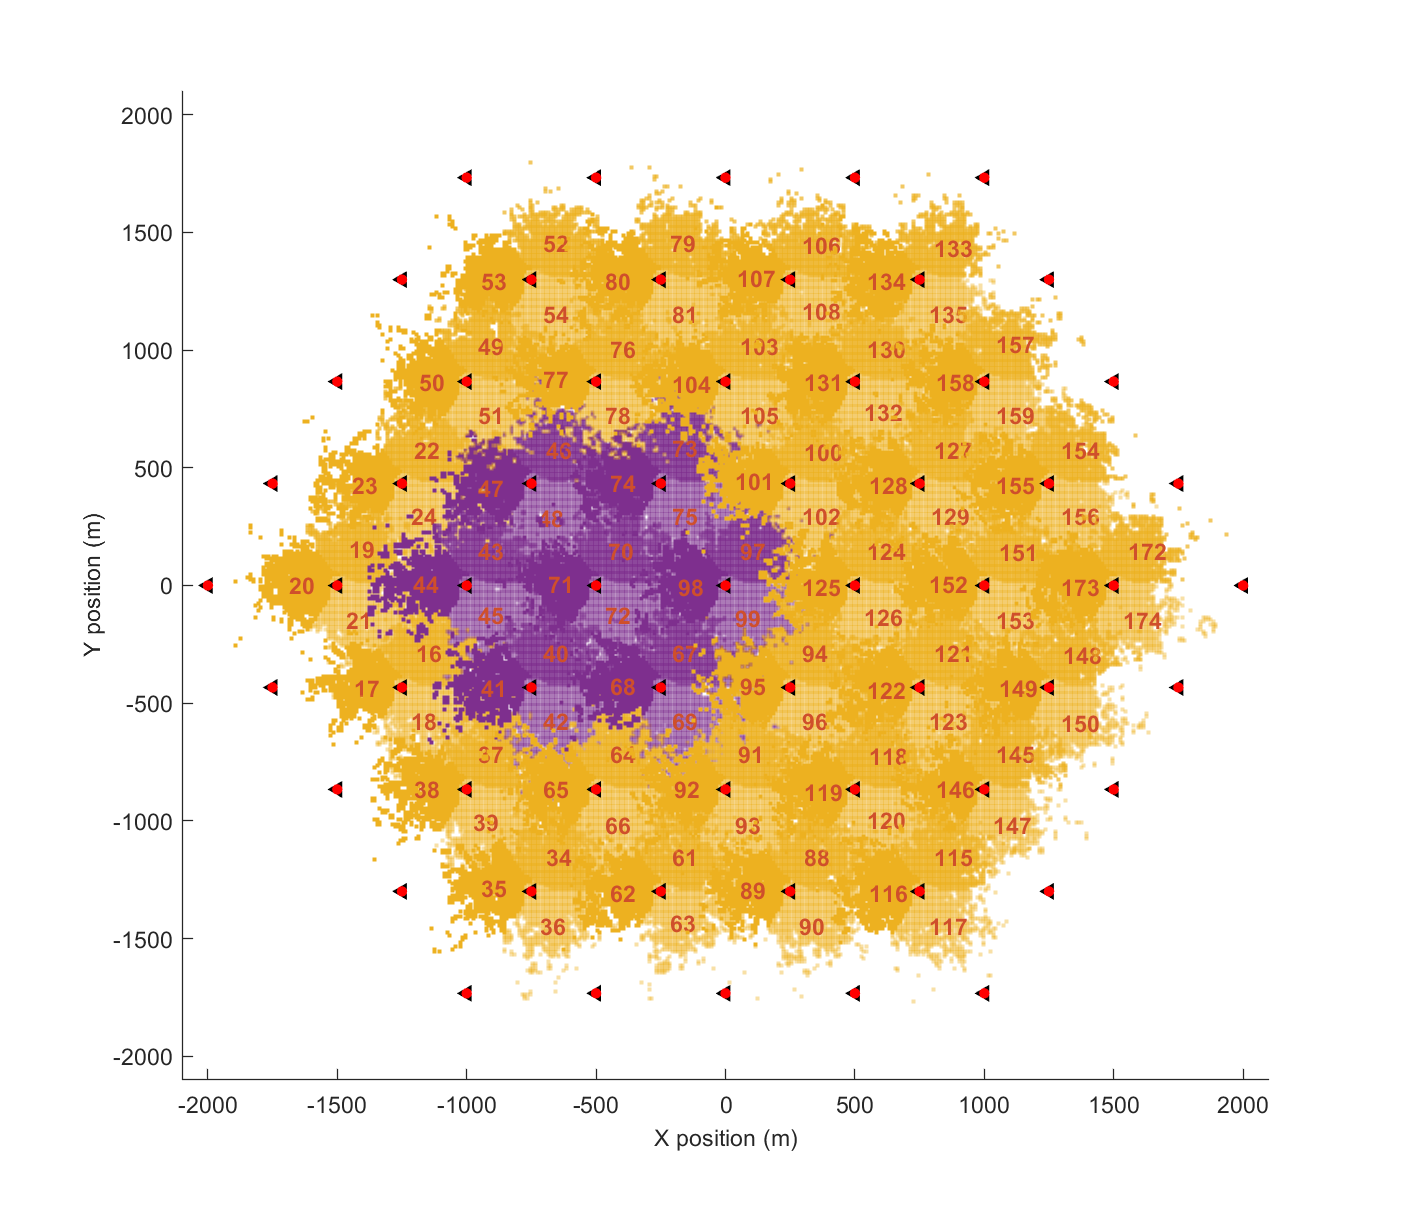

switch area
    case "Center"
        plot_MBSFN(center_c_list, x_lim, y_lim, mk_size, f_h);
    case "Left"
        plot_MBSFN(left_c_list, x_lim, y_lim, mk_size, f_h, purple);
    case "Upleft"
        plot_MBSFN(upleft_c_list, x_lim, y_lim, mk_size, f_h, green);
end

**Intersected area (deep red color) we interested.**

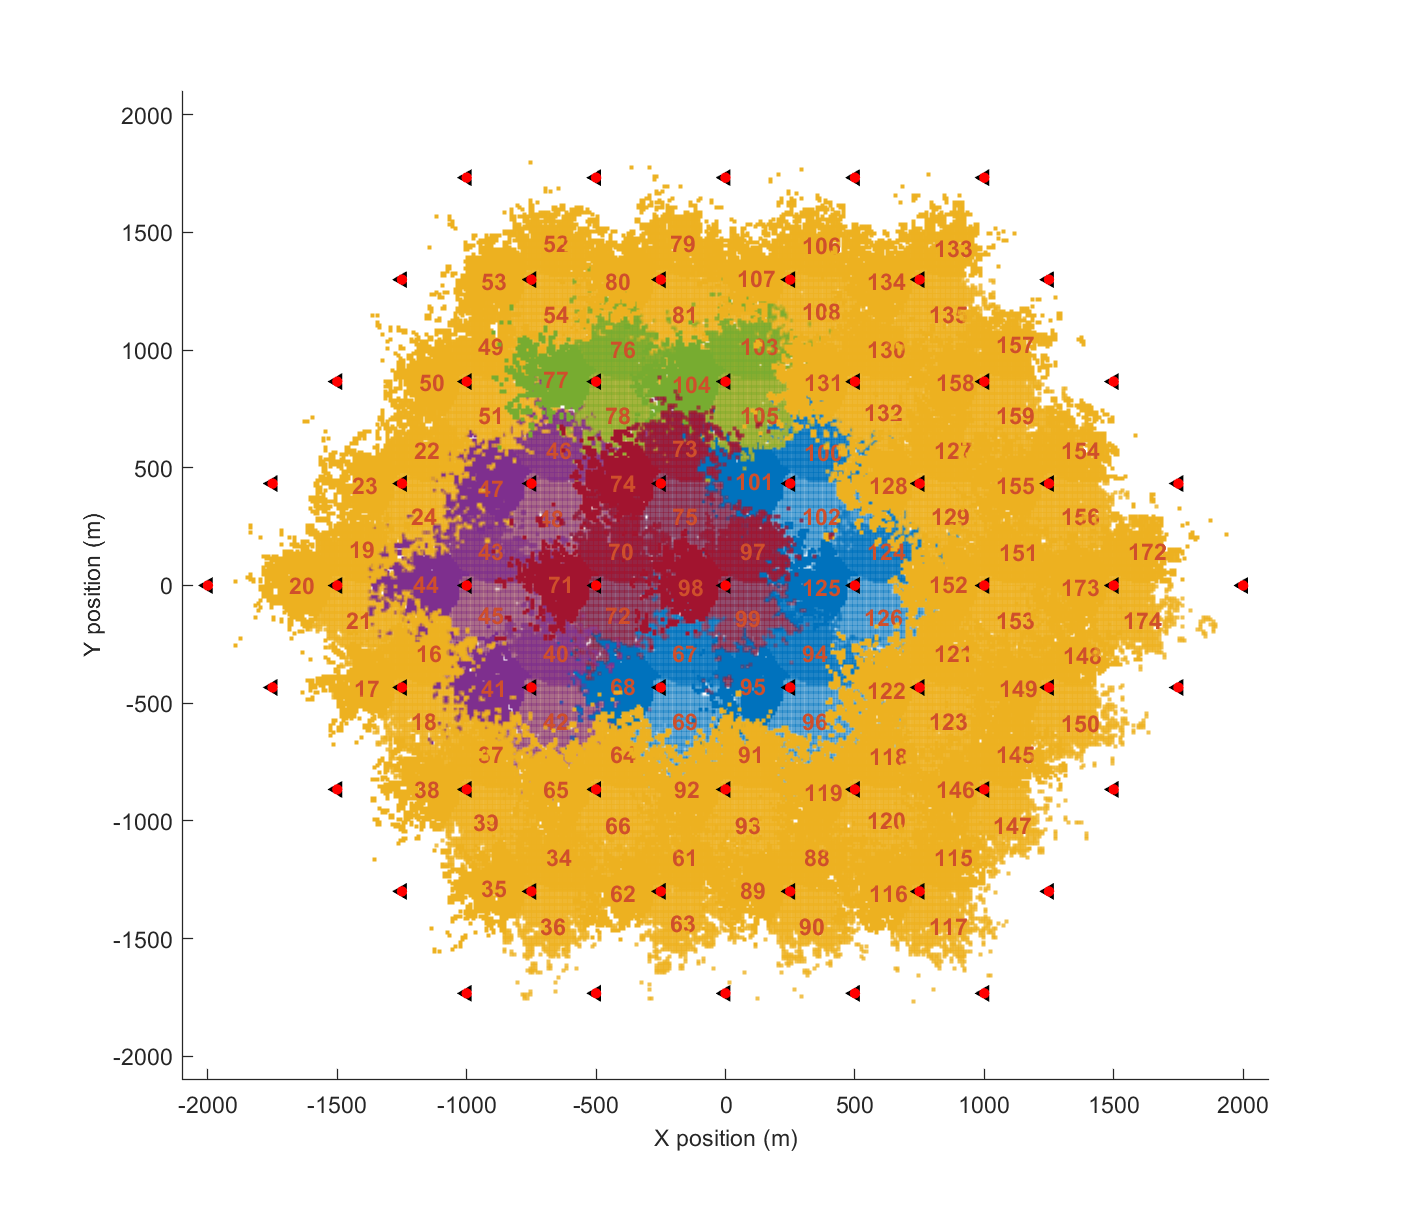

date = [0.6350, 0.0780, 0.1840];
f_h = figure("Position", [0, 0, 801, 693]);
f_h = plot_MBSFN(center_c_list, x_lim, y_lim, mk_size, f_h);
f_h = plot_MBSFN(left_c_list, x_lim, y_lim, mk_size, f_h, purple, center_c_list);
f_h = plot_MBSFN(upleft_c_list, x_lim, y_lim, mk_size, f_h, green, unique([center_c_list, left_c_list]));
intersection = intersect(intersect(center_c_list, left_c_list), upleft_c_list);
all = 1:183;
plot_MBSFN(intersection, x_lim, y_lim, mk_size, f_h, date, setdiff(all, intersection));

**CQI cut.**

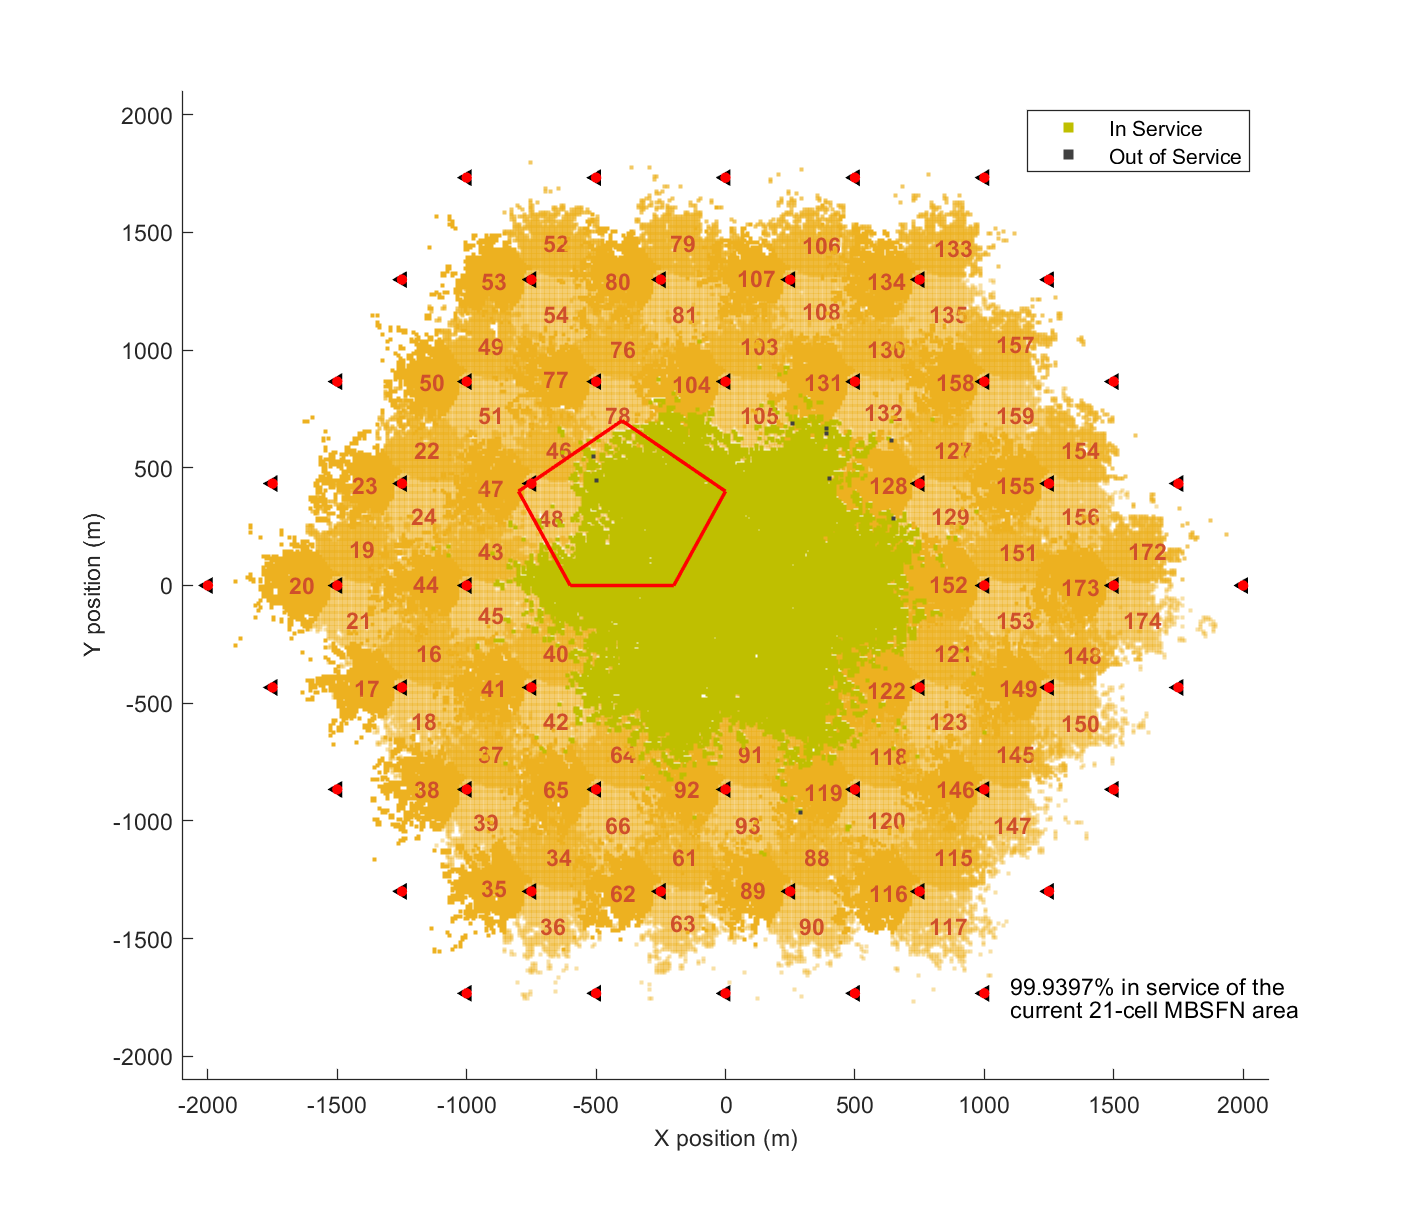

% minimum SINR value for corresponding CQI from 1 to 15.
M_CQI_list = [-7.05, -5.25, -3.25, -1.3, 0.65, ...
                2.7, 4.7, 6.55, 8.55, 10.6, ...
                12.5, 14.5, 16.2, 18.2, 20.5];
triangle = [-350, -700, 100; ...
            -150, 600, 500];
rectangle = [-700, 0, 0, -700; ...  % [X1,..., Xn; Y1, ..., Yn]
                0, 0, 700, 700];
pentagon = [-600, -800, -400, 0, -200; ...
            0, 400, 700, 400, 0];
hexagon = [-600, -800, -600, -200, 0, -200; ...
            0, 400, 800, 800, 400, 0];
octagon = [-600, -800, -800, -600, -200, 0, 0, -200; ...
            0, 200, 600, 800, 800, 600, 200, 0];
        
Interested_area = pentagon;
CQI =  8;
area = "Center";
Interested_area_only = true;
if CQI == 0
   SINR = -Inf;
else
    SINR = M_CQI_list(CQI);
end
f_h = figure("Position", [0, 0, 801, 693]);
if Interested_area_only
    plot_MBSFN_SINR(area, SINR, x_lim, y_lim, mk_size, f_h, Interested_area);
else
    plot_MBSFN_SINR(area, SINR, x_lim, y_lim, mk_size, f_h);
end

**Focus on interested area and "in service percentage".**

**Plots only shows coverage related to the 3 MBSFN areas.**

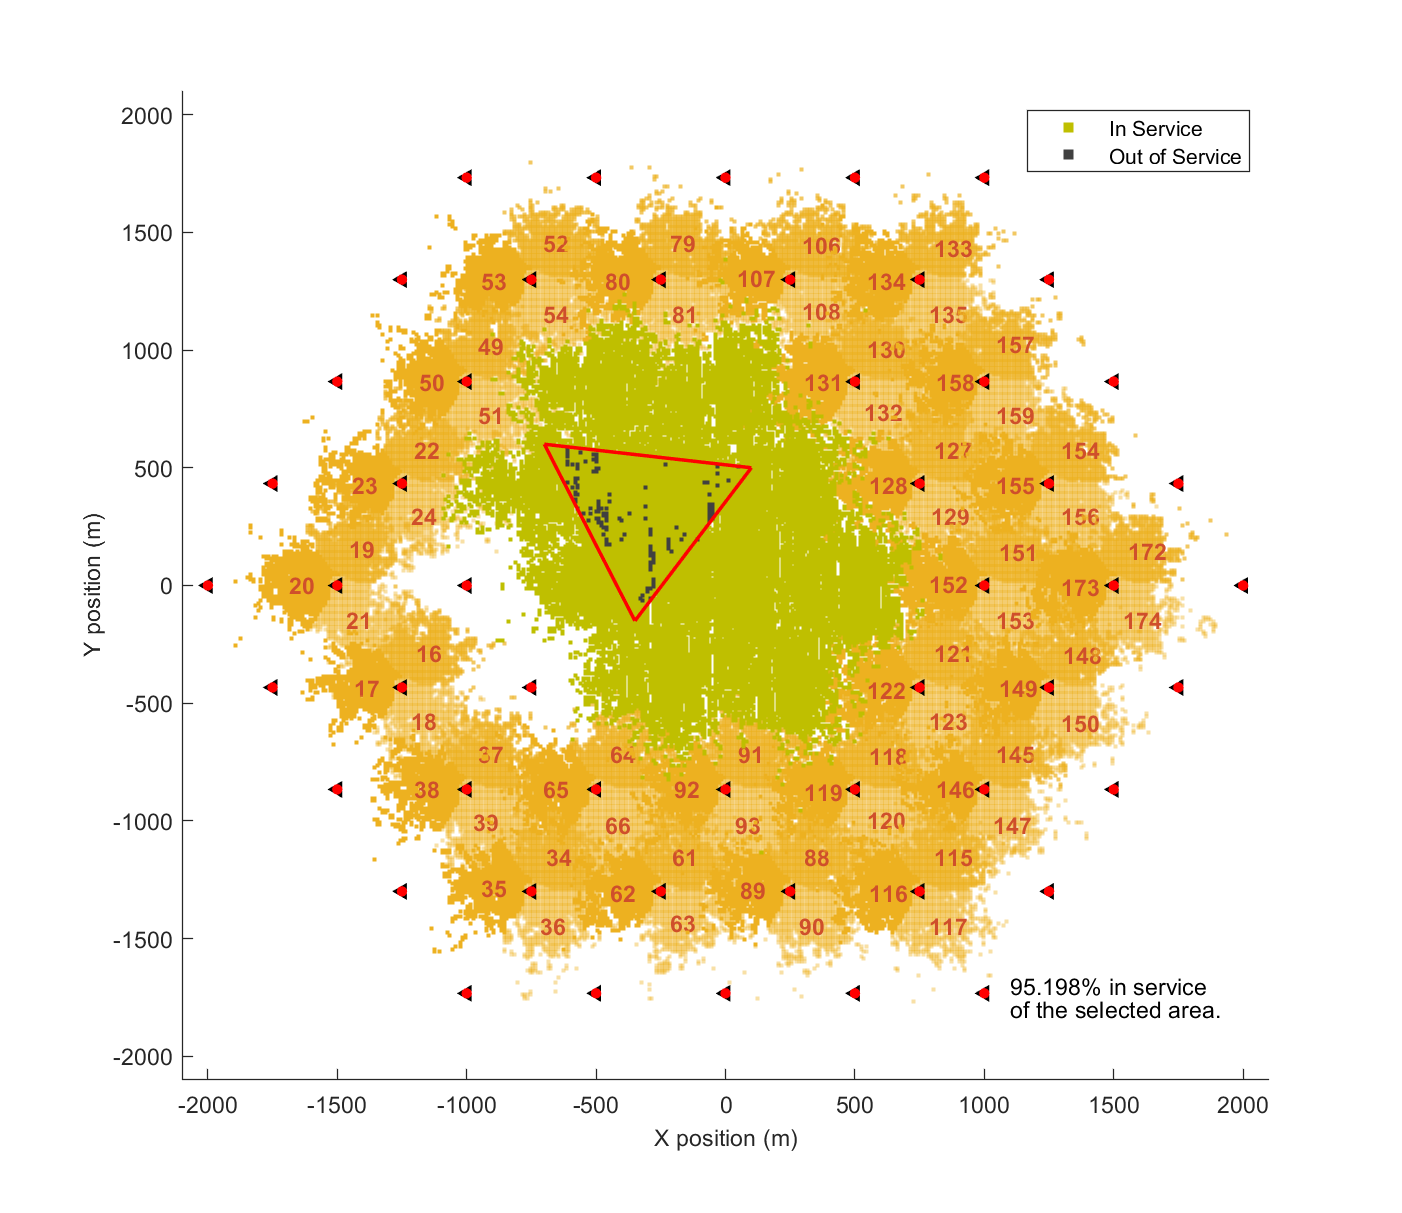

Interested_area = triangle;
CQI =  12;
SINR = M_CQI_list(CQI);
center = true; % center MBSFN area serves
left = false; % left MBSFN area serves
upleft = true; % upleft MBSFN area serves
overshooting_exclude = true;
f_h = figure("Position", [0, 0, 801, 693]);
plot_MBSFN_SINR_3areas(center, left, upleft, SINR, x_lim, y_lim, mk_size, f_h, Interested_area, overshooting_exclude);